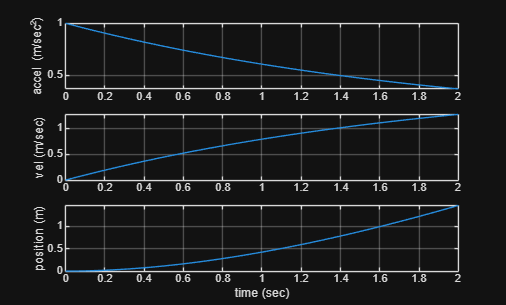

syms a_sym v_sym x_sym t

a_sym = exp(-0.5*t);
v_sym = int(a_sym, 0, t);
x_sym = int(v_sym, 0, t);

a = matlabFunction(a_sym);
v = matlabFunction(v_sym);
x = matlabFunction(x_sym);

subplot(3,1,1)
fplot(a,[0 2])
grid on
ylabel('accel (m/sec^2)')

subplot(3,1,2)
fplot(v,[0 2])
grid on
ylabel('vel (m/sec)')

subplot(3,1,3)
fplot(x,[0 2])
grid on
ylabel('position (m)')
xlabel('time (sec)')  % issue was here: use % and add subplot(3,1,3)